w = [0 20 40 60 80 100 120 140 160 180 200]

w =      0    20    40    60    80   100   120   140   160   180   200


va = [2.2 3.2 5.2 7.0 8.8 10.3 11.2 13.2 14.2 16.4 18.0]

va =     2.2000    3.2000    5.2000    7.0000    8.8000   10.3000   11.2000   13.2000   14.2000   16.4000   18.0000


vb = [2.2 5.3 10.0 12.6 17.1 20.0 24.0 27.8 30.6 34.2 37.0]

vb =     2.2000    5.3000   10.0000   12.6000   17.1000   20.0000   24.0000   27.8000   30.6000   34.2000   37.0000


vc = -[0.5 -3.0 -7.2 -11.8 -16.2 -20.3 -24.9 -29.6 -34.4 -38.6 -43.3]

vc =    -0.5000    3.0000    7.2000   11.8000   16.2000   20.3000   24.9000   29.6000   34.4000   38.6000   43.3000


Sa = diff(va)/diff(w)

Sa = 0.0790

Sb = diff(vb)/diff(w)

Sb = 0.1740

Sc = diff(vc)/diff(w)

Sc = 0.2190

wba = polyfit(w, va, 1)

wba =     0.0789    2.0818


difa = abs(va - (wba(1) .* w + wba(2)))

difa =     0.1182    0.4600    0.0382    0.1836    0.4055    0.3273    0.3509    0.0709    0.5073    0.1145    0.1364


deltaa = max(difa)/va(end)

deltaa = 0.0282


wbb = polyfit(w, vb, 1)

wbb =     0.1767    2.4045


difb = abs(vb - (wbb(1) .* w + wbb(2)))

difb =     0.2045    0.6382    0.5282    0.4055    0.5609    0.0727    0.3936    0.6600    0.0736    0.0073    0.7409


deltab = max(difb)/vb(end)

deltab = 0.0200


wbc = polyfit(w, vc, 1)

wbc =     0.2215   -1.3500


difc = abs(vc - (wbc(1) .* w + wbc(2)))

difc =     0.8500    0.0800    0.3100    0.1400    0.1700    0.5000    0.3300    0.0600    0.3100    0.0800    0.3500


deltac = max(difc)/vc(end)

deltac = 0.0196

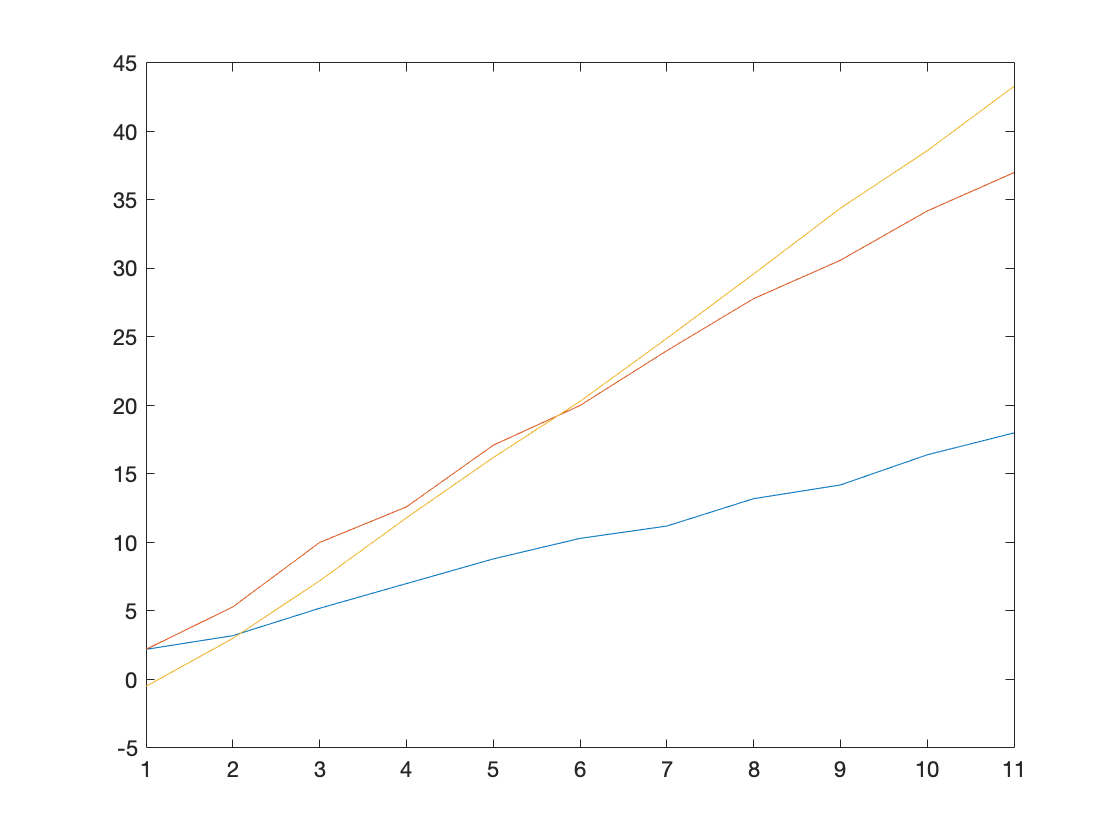

plot(va,'DisplayName','va');hold on;plot(vb,'DisplayName','vb');plot(vc,'DisplayName','vc');hold off;